%Setting up the x and y values

x=[1,2,4,7];
y=[7.2,14.5,9.7,10.2];

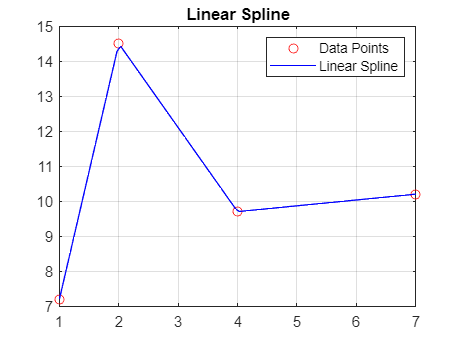

%Linear Spline:

slopes=[];
intercepts=[];
for i=1:length(x)-1
    slopes(end+1)=(y(i+1)-y(i))/(x(i+1)-x(i));
    intercepts(end+1)=y(i)-(y(i+1)-y(i))/(x(i+1)-x(i))*x(i);
end

x_lin=linspace(x(1),x(end));
y_lin=[];
for i=1:length(x_lin)
    for j=1:length(x)-1
        if x(j+1)>=x_lin(i) && x(j)<=x_lin(i)
            y_lin(end+1)=slopes(j)*x_lin(i)+intercepts(j);
        end
    end
end

plot(x,y,'ro')
hold on
plot(x_lin,y_lin,'b')
hold off
grid on
title('Linear Spline')
legend('Data Points','Linear Spline')

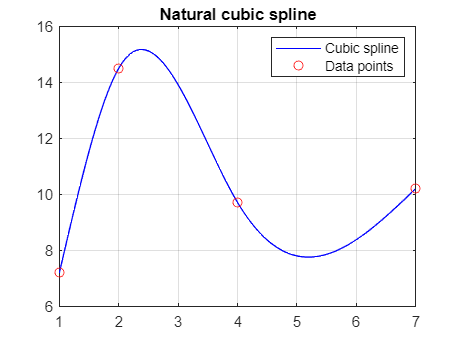

% Cubic spline

n=length(x) -1;

x_cub=zeros(1,n+1); 
a=zeros(1,n+1);

for i=0:n
    x_cub(i+1)=x(i+1);
    a(i+1)=y(i+1);
end

m=n-1;
h=zeros(1,m+1);
for i=0:m
    h(i+1)=x(i+2)-x(i+1);
end

xa=zeros(1,m+1);
 
for i=1:m
    xa(i+1)=3.0*(a(i+2)*h(i)-a(i+1)*(x(i+2)-x(i))+a(i)*h(i+1))/(h(i+1)*h(i));
end

x1=zeros(1,n+1); x1(1) = 1;
xu=zeros(1,n+1); xu(1) = 0;
xz=zeros(1,n+1); xz(1) = 0;

for i=1:m
    x1(i+1)=2*(x(i+2)-x(i))-h(i)*xu(i);
    xu(i+1)=h(i+1)/x1(i+1);
    xz(i+1)=(xa(i+1)-h(i)*xz(i))/x1(i+1);
end

x1(n+1)=1;
xz(n+1)=0;


b=zeros(1,n+1);
c=zeros(1,n+1);
d=zeros(1,n+1);
c(n+1)=xz(n+1);

for i=0:m
    j=m-i;
    c(j+1)=xz(j+1)-xu(j+1)*c(j+2);
    b(j+1)=(a(j+2)-a(j+1))/h(j+1)-h(j+1)*(c(j+2)+2.0*c(j+1))/3.0;
    d(j+1)=(c(j+2)-c(j+1))/(3.0*h(j+1));
end

inter_n=100;
x_cub_inter=linspace(x(1),x(end),inter_n);
y_cub_inter=[];

syms xf;
for i =1:length(x)-1
    s(i)=vpa(simplify(a(i)+b(i).*(xf-x(i))+c(i).*(xf-x(i)).^2+d(i).*(xf-x(i)).^3));
end 

inter_n=100;
for i = 1:length(x)-1
    xv=x(i):((length(x)+1)/inter_n):x(i+1);
    yv=double(vpa(subs(s(i),xf,xv)));
    plot(xv,yv,'b')
    hold on
    plot(x,y,'ro')
end
hold off
grid on
legend('Cubic spline','Data points');
title('Natural cubic spline');